# Actividad 4.1 Trozos. 

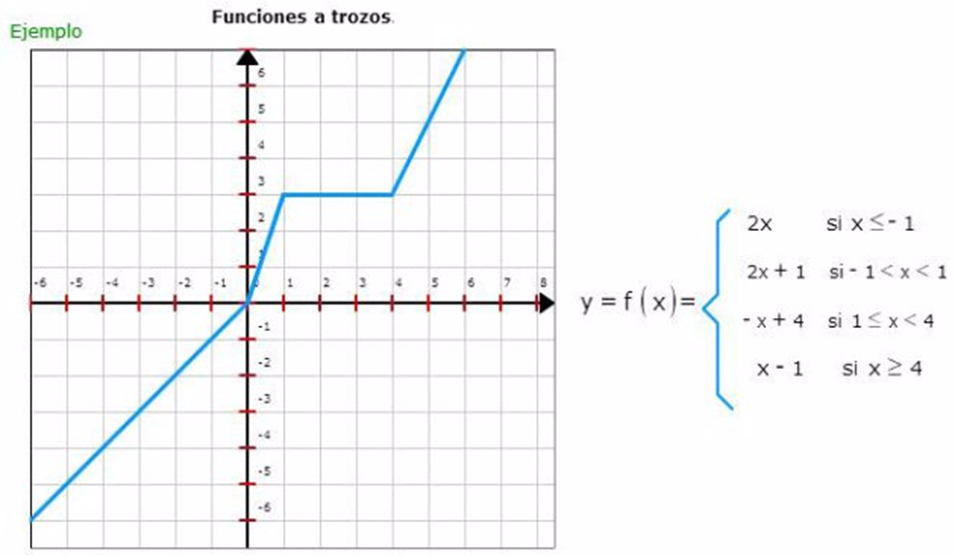

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    Cambiamos el tiempo para que de esta manera no tuviera problemas con las dimensiones ademas de cumplir con la ruta de la simulación.

tf = 11;             % Tiempo de simulacion en segundos (s) 
ts = 0.2;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

La posición en este caso tambien cambia conforme a la imagen de muestra, para cumplir con las especificaciones del modelo de ruta. 

x1(1) = -5;    % Posicion inicial eje x   
y1(1) = -5;   % Posicion inicial eje y
phi(1) = pi/4;   % Orientacion inicial del robot

%sigzag
%x1(1) = -5;    % Posicion inicial eje x   
%y1(1) = -5;   % Posicion inicial eje y

%circulo
%x1(1) = 4;    
%y1(1) = 0;

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(2, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(2, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%   0*ones(1,6)  ,,   pi/2*ones(1,6)

Se fueron probando distintos rangos con el fin de ver los angulos y distancias correctas, con el fin de alcanzar los mismos aspectos que la de referencia, ademas de dividir un vector de distancia por que al momento de correr el código hubo complicaciones (vector inicial partido en tres). 

%zigzag 
u =[ 2.35*ones(1,5)  2.35*ones(1,5) 2.35*ones(1,5) 0*ones(1,5)       2.0*ones(1,8)    0*ones(1,5)       3*ones(1,5)   0*ones(1,5)   3.35*ones(1,13)];
w =[ 0*ones(1,5)   0*ones(1,5) 0*ones(1,5) 0.455959*ones(1,5)   0*ones(1,8)  4.825*pi/3*ones(1,5) 0*ones(1,5)  1.05*ones(1,5) 0*ones(1,13)];
%pi/6

Se presentan los resultados de como es que la simulación cumple con los puntos clave de la figura. 

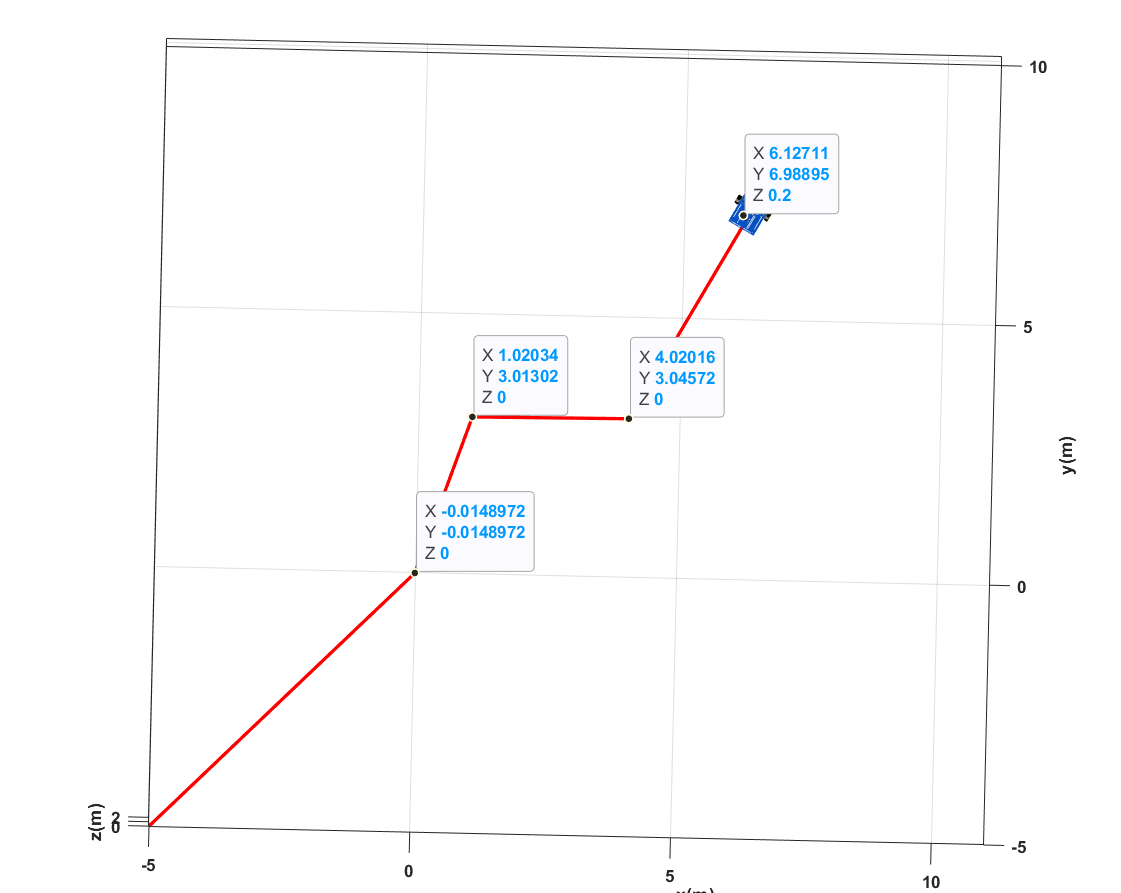

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

En esta parte podemos decir que se expandio la orientación o tamaño del plano de la simulación ademas de sus limites minimos y maximos de los ejes, para que se pudiera obtener y observar toda la simulación. 

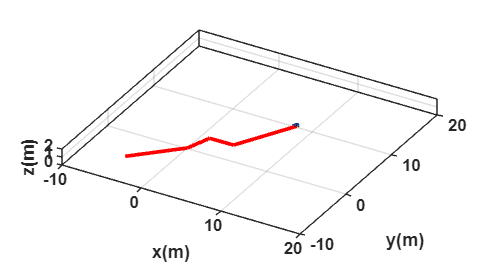

view([30 30]); % Orientacion de la figura
axis([-10 20 -10 20 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

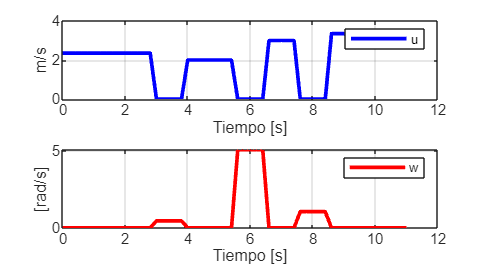


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');